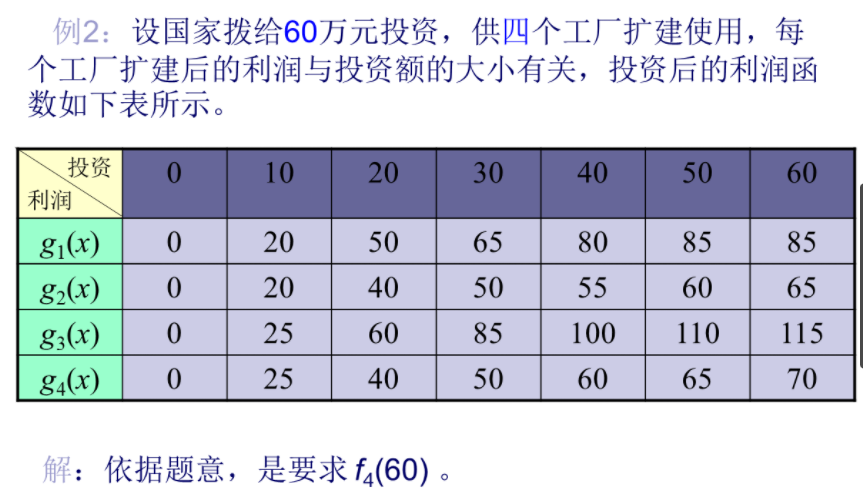

clc;clear
g=[0 20 50 65 80 85 85
    0 20 40 50 55 60 65
    0 25 60 85 100 110 115
    0 25 40 50 60 65 70];
%顺序求解
row=size(g,1);
col=size(g,2);
stage=row;
choose=strings(row*2,col);
choose(1,:)=g(1,:);
choose(2,:)=0:10:60;
count=3;
f=g(1,:);
for i=2:stage
    f_next=zeros(col,1);
    for x=60:-10:0
        storage=zeros(x/10+1,1);
        for y=0:10:x
            storage(y/10+1)=g(i,y/10+1)+f((x-y)/10+1);
        end
        
        
        temp_max=max(storage);
        temp_num=find(storage==temp_max)';
        choose(count,x/10+1)=num2str(temp_max);
        choose(count+1,x/10+1)=num2str((temp_num-1)*10);
        %         if i==stage
        %             f_next=storage;
        %             break;
        %         end
        f_next(x/10+1)=temp_max; 
    end
    count=count+2;
    f=f_next;
end
choose

choose = 8×7 string 数组
    "0"    "20"       "50"    "65"       "80"       "85"       "85" 
    "0"    "10"       "20"    "30"       "40"       "50"       "60" 
    "0"    "20"       "50"    "70"       "90"       "105"      "120"
    "0"    "0  10"    "0"     "10"       "20"       "20"       "20" 
    "0"    "25"       "60"    "85"       "110"      "135"      "155"
    "0"    "10"       "20"    "30"       "20"       "30"       "30" 
    "0"    "25"       "60"    "85"       "110"      "135"      "160"
    "0"    "0  10"    "0"     "0  10"    "0  10"    "0  10"    "10" 


MYFUN(60,10,8,7,choose); 

Generator_load = 10

Generator_load = 30

Generator_load = 0

Generator_load = 20